% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\cubeWithHole.STL");
trisurf(stl1)
hold on
% stl1 = stlread("Test Objects\cylinder.STL");
% stl1 = stlread("Test Objects\box.STL");
% stl1 = stlread("Test Objects\keys.STL");

% Create UniformSliceGeneratorObject
sliceHeight = 2;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 2
           slicePath: []
           slicerTol: 1.0000e-07


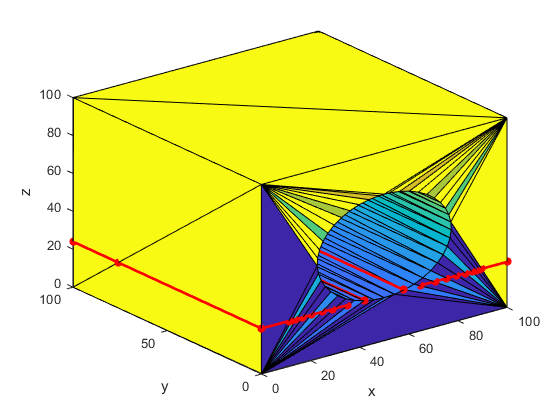


test = uSGO1.slice(24);
for j = 1:max(test(:,4))

    pathPlotPoints = test(test(:,4) == j,:);
    plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r*','LineWidth',2);
    hold on

end
xlabel('x')
ylabel('y')
zlabel('z')

% Generate
view(3);

figure(3)
uSGO1.generateSlices()
op = uSGO1.getSlicePath()

% Show
figure(4)

for i = 0:sliceHeight:double(max(op(:,3)))
    
    zPlotPoints = op(op(:,3) == i,:);
    
    for j = 1:max(zPlotPoints(:,4))
    
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on

    end

end

xlabel('x')
ylabel('y')
view(3);
hold on